This live script aims to compare the global catalog and the californian catalog in a single plot. Particularly with respect the the focal mechanism dependence on productivity.

## remember to adjust Mth in kernel function!

focalMechanismArray = {'strike slip','normal','reverse'};
fnArray = {'/auto/home/kdascher/Documents/UCSC/general_data/Earthquake_data/SCEDC/SCEDC_CAT.mat',...
           'eq_catalog.mat'};%, ...
           %'/auto/home/kdascher/Documents/UCSC/general_data/Earthquake_data/JMA/JMA_nodal_cat.mat'};
% Initialize variablesc 
[k,alpha,Mmin] =  deal(zeros(length(fnArray),length(focalMechanismArray)));
[Mag,MagCount] =  deal(cell( length(fnArray),length(focalMechanismArray)));

for m = 1:length(fnArray)
    for n = 1:3
        [k(n,m),alpha(n,m),~,~,Mmin(n,m),Mag{n,m},MagCount{n,m}] = aftershock_productivity_kernel(fnArray{m}, ...
            'DepthRange',[0,55], ...
            'FocalMechanism', focalMechanismArray{n}, ...
            'TimeRange',[datenum(1990,01,01), datenum(2017,01,01)],... 
            'PlotYN','no');
    end
end



Correct the number of aftershocks so that they are on the same basis:

lowestMmin = min(min(Mmin));

plot the corrected output

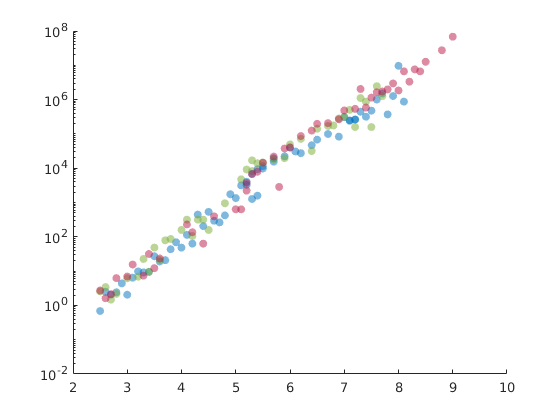

figure; hold on;    
colors              = {[0         0.4470    0.7410]; ...
                       [0.4660    0.6740    0.1880]; ...
                       [0.7350    0.0880    0.2840]}; % set this
shapes = {'o','diamond'};
for m = 1:length(fnArray)
    for n = 1:3
        b = 1; 
        MagCountCorr    = MagCount{n,m}*10^(b*(Mmin(n,m)-lowestMmin));
        scatter(Mag{n,m},MagCountCorr,[],colors{n},'filled','MarkerFaceAlpha',0.5)
    
    end
end

set(gca,'YScale','log')

load handel
sound(y,Fs)